已知$L_1=50,L_2=40,L_3=60$，坐标系和角度如下图所示

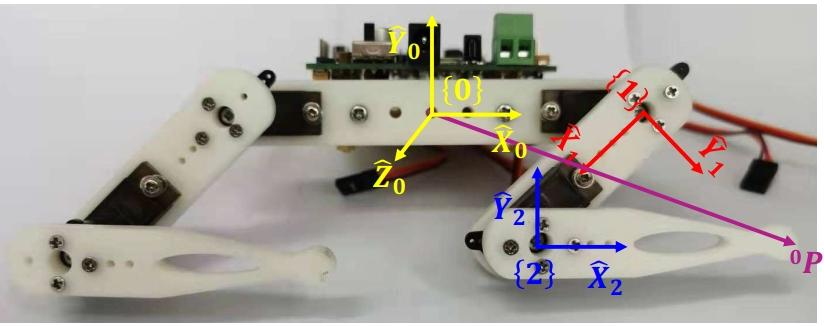

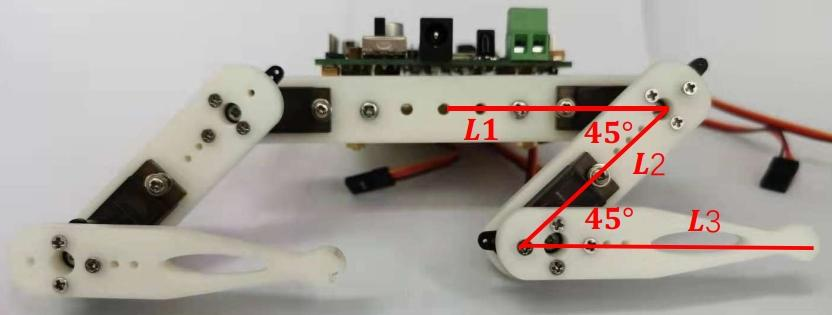

列出$\mathrm{DH}$参数表


$$\left\lbrack \begin{array}{ccccc}
i & \alpha_{i-1}  & a_{i-1}  & d_i  & \theta_i \\
1 & 0 & L_1  & 0 & -135\\
2 & 0 & L_2  & 0 & 135
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccccc}
i & \alpha_{i-1}  & a_{i-1}  & d_i  & \theta_i \\
1 & 0 & 50 & 0 & -135\\
2 & 0 & 40 & 0 & 135
\end{array}\right\rbrack$$


写出$P$点在坐标系$\left\lbrace 2\right\rbrace$下的坐标


$${}^2P={\left\lbrack \begin{array}{ccc}
60 & 0 & 0
\end{array}\right\rbrack }^T$$


P_2 = [60 0 0]';
P_2_tmp = [P_2;1];

计算$i=1$时的$DH$矩阵${}^0T_1$

T_0_1 = get_DH_matrix(0,50,0,-135);

计算$i=2$时的$DH$矩阵${}^1T_2$

T_1_2 = get_DH_matrix(0,40,0,135);

求解${}^0P$

P_0_tmp = T_0_1*T_1_2*P_2_tmp;

P_0_tmp =    81.7157
  -28.2843
         0
    1.0000


P_0 = P_0_tmp(1:3,1)

P_0 =    81.7157
  -28.2843
         0
